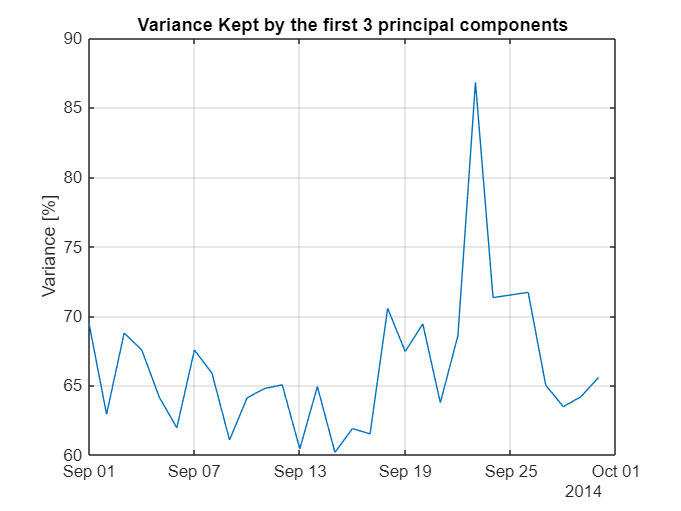

path = uigetdir;
files = dir(path);
nrFiles = length(files);

varKept = zeros(nrFiles-2, 1);
timeForPlotting = datetime(zeros(nrFiles-2, 1), 'ConvertFrom', 'datenum');
for i = 3:nrFiles
    fileName = files(i).name;
    filePath = files(i).folder;
    fullFileName = fullfile(filePath, fileName);
    load(fullFileName);
    % Convert to matrix
    dataMat = dataTT{:,:};
    % Extract time and channel names
    timeVec = dataTT.Properties.RowTimes;
    channelNames = dataTT.Properties.VariableNames;
   % Remove NaNs from data
    rowsWithNans = sum(isnan(dataMat),2);
    dataMat(rowsWithNans>0, :) = [];
    % Normalize data
    stdData = std(dataMat);
    stdData(stdData==0) = 1; % This line ensures, that we don't divide with 0.
    dataMat = (dataMat - mean(dataMat))./stdData;
    % Perform PCA
    [U,S,V] = svd(dataMat, 0);
    nrVarSaved = 3;
    % Compute the variance saved
    sumOfDiag = sum(sum(S.^2));
    matVar = 100*S.^2./sumOfDiag;
    varKept(i-2) = sum(sum(matVar(1:nrVarSaved, 1:nrVarSaved)));
    timeForPlotting(i-2) = timeVec(1);
end  

figure
plot(timeForPlotting,varKept);
title('Variance Kept by the first 3 principal components')
grid on;
ylabel('Variance [%]')

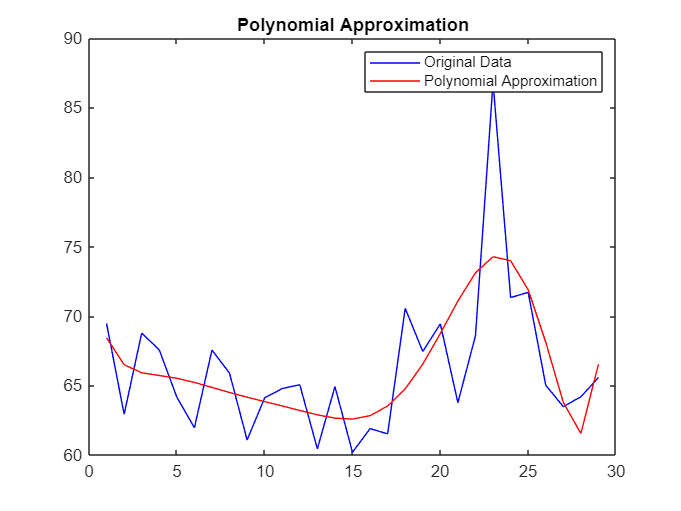

% Part b: Polynomial Approximation
poly_degree = 8; % Assuming cubic approximation
x = 1:size(varKept, 1);
y = varKept(:, 1); % Example using the first column
p = polyfit(x, y, poly_degree);
y_poly = polyval(p, x);
figure;
plot(x, y, 'b', x, y_poly, 'r');
title('Polynomial Approximation');
legend('Original Data', 'Polynomial Approximation');


% Part c: Residual Analysis
residual = y - y_poly;
mean_residual = mean(residual);
median_residual = median(residual);
std_residual = std(residual);
iqr_residual = iqr(residual);


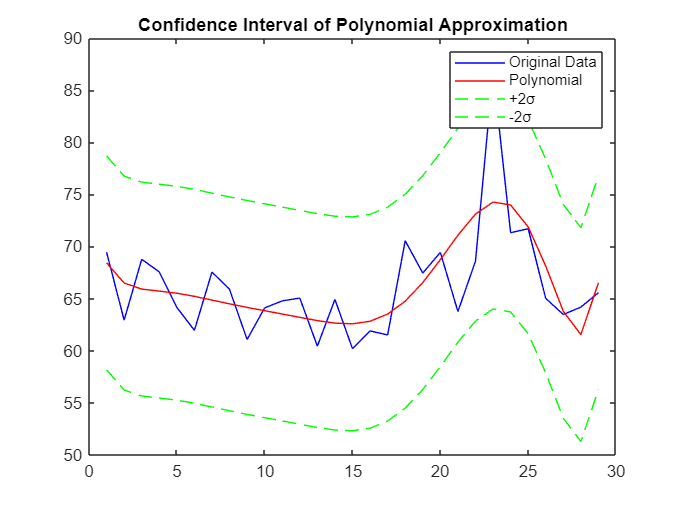

% Part d: Confidence Interval
upper_bound = y_poly + 2 * std_residual;
lower_bound = y_poly - 2 * std_residual;
figure;
plot(x, y, 'b', x, y_poly, 'r', x, upper_bound, 'g--', x, lower_bound, 'g--');
title('Confidence Interval of Polynomial Approximation');
legend('Original Data', 'Polynomial', '+2σ', '-2σ');

% Part e: Prediction for 1st October
predicted_value = polyval(p, size(varKept, 1) + 1);


% Part f: Comparison with Actual Value
load("LoaderB14-10-01.mat");
% Convert to matrix
dataMat = dataTT{:,:};


% Remove NaNs from data
rowsWithNans = sum(isnan(dataMat),2);
dataMat(rowsWithNans>0, :) = [];
% Normalize data
stdData = std(dataMat);
stdData(stdData==0) = 1; % This line ensures, that we don't divide with 0.
dataMat = (dataMat - mean(dataMat))./stdData;


% Perform PCA
[U,S,V] = svd(dataMat, 0);
nrVarSaved = 3;
% Compute the variance saved
sumOfDiag = sum(sum(S.^2));
matVar = 100*S.^2./sumOfDiag;
varKeptOct = sum(sum(matVar(1:nrVarSaved, 1:nrVarSaved)))

varKeptOct = 61.8425

fprintf('Predicted Value: %.2f\n', predicted_value);

Predicted Value: 87.28


fprintf('Actual Value: %.2f\n', varKeptOct);

Actual Value: 61.84


## % Exercise 2: Interpolation and Regularization

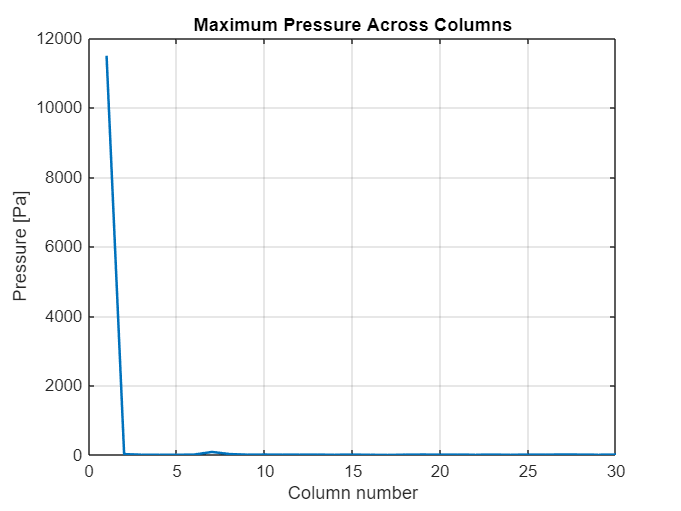

% Part a: Load and Transform Data
interp_data = readmatrix('Interpolation_Edge_D.csv');
[maxVal, idx] = max(interp_data);

% Plot maximum values across columns
figure;
plot(maxVal, 'LineWidth', 1.5);
grid on;
xlabel('Column number');
ylabel('Pressure [Pa]');
title('Maximum Pressure Across Columns');

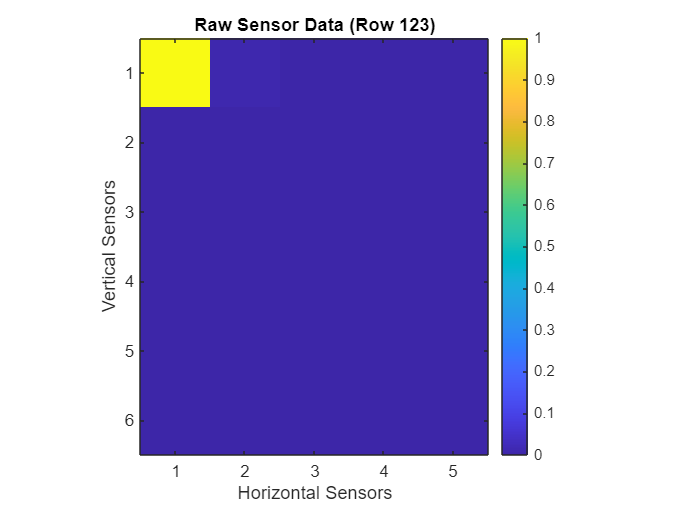


% Identify maximum value location
[~, colMax] = max(maxVal);
rowMax = idx(colMax);
rowData = interp_data(rowMax, :) - interp_data(2, :);
rowData = rowData ./ max(max(rowData));

% Reshape data to sensor grid
nrSensorHor = 5;
nrSensorVer = 6;
sensorData = reshape(rowData, nrSensorVer, nrSensorHor);

% Plot raw sensor data
figure;
imagesc(sensorData);
axis image;
title(['Raw Sensor Data (Row ', num2str(rowMax), ')']);
xlabel('Horizontal Sensors');
ylabel('Vertical Sensors');
colorbar;

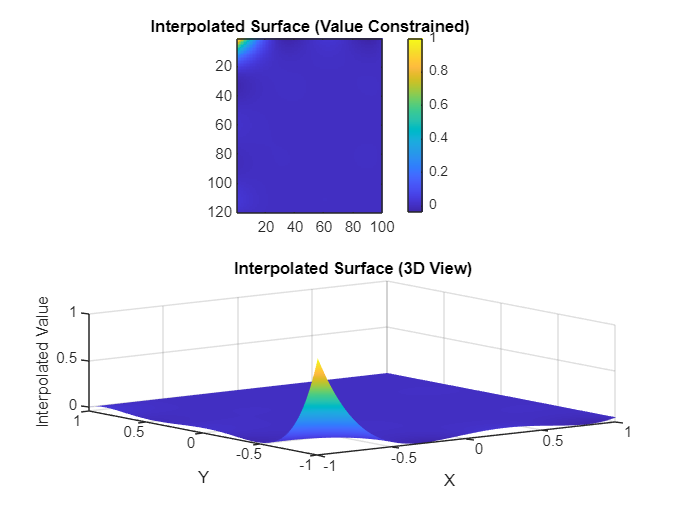


% Define polynomial degrees and Vandermonde matrices
degX = size(sensorData, 2) - 1;
degY = size(sensorData, 1) - 1;
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Vx = vander(x);
Vy = vander(y);

Cx = Vx;
Cy = Vy([end-1 end], :);

% Perform constrained interpolation
kronP = kron(Cx, Cy);
N = null(kronP);
vecCoeffsDer = N * pinv(kron(Vx, Vy) * N) * sensorData(:);
valConCoeffs = reshape(vecCoeffsDer, degY + 1, degX + 1);

% Interpolation surface for plotting
factor = 20;
xPlot = linspace(-1, 1, factor * nrSensorHor);
yPlot = linspace(-1, 1, factor * nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);

[xSurf, ySurf] = meshgrid(xPlot, yPlot);
interpSurfaceDVC = VyPlot * valConCoeffs * VxPlot';

% Plot interpolation results
figure;
subplot(2, 1, 1);
imagesc(interpSurfaceDVC);
axis image;
title('Interpolated Surface (Value Constrained)');
colorbar;

subplot(2, 1, 2);
surf(xSurf, ySurf, interpSurfaceDVC);
shading interp;
title('Interpolated Surface (3D View)');
xlabel('X');
ylabel('Y');
zlabel('Interpolated Value');

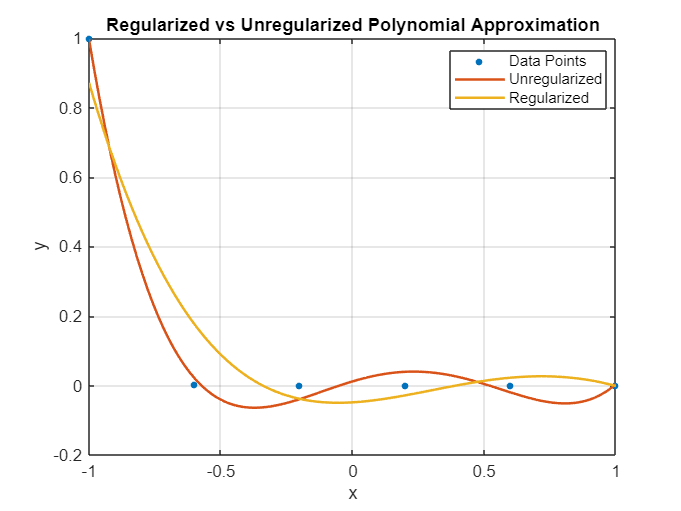


% Part b: Regularized Polynomial Approximation
tikData = sensorData(:, 1); % Select a column of sensor data
degree = 4;
vFull = vander(y);
V = vFull(:, end-degree:end);
alpha = pinv(V) * tikData;

% Regularization setup
d = degree:-1:1;
M = diag(d, -1);
dV = V * M;

lambda = 1e-2;
bigV = [V; sqrt(lambda) * dV];
bigY = [tikData; zeros(size(dV, 1), 1)];
alphaReg = pinv(bigV) * bigY;

% Plot regularized and unregularized results
nrPtsPlot = 100;
xPlot = linspace(-1, 1, nrPtsPlot);
yPlot = polyval(alpha, xPlot);
yPlotReg = polyval(alphaReg, xPlot);

figure;
plot(y, tikData, '.', 'MarkerSize', 12);
hold on;
plot(xPlot, yPlot, 'LineWidth', 1.5);
plot(xPlot, yPlotReg, 'LineWidth', 1.5);
grid on;
xlabel('x');
ylabel('y');
title('Regularized vs Unregularized Polynomial Approximation');
legend('Data Points', 'Unregularized', 'Regularized', 'Location', 'Best');